**Generation of Am signal using square law modulation**

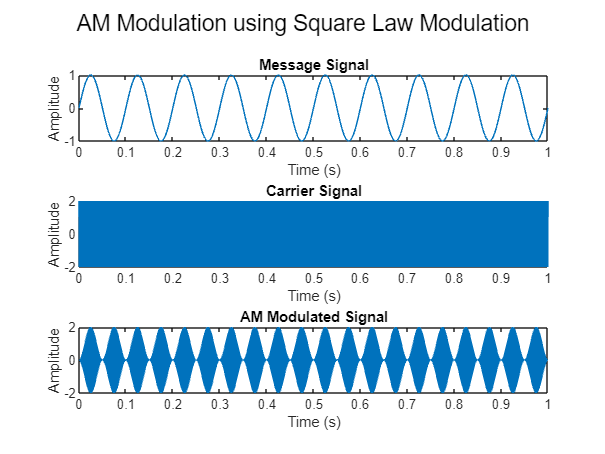

% define parameters
fc = 1000;  
fm = 10;
fs = 10000;       
t = 0:1/fs:1;      
Am = 1;            
Ac = 2;            

% message signal
message_signal = Am * sin(2 * pi * fm * t);

% carrier signal
carrier_signal = Ac * cos(2 * pi * fc * t);

% square law modulation
modulated_signal = message_signal .* message_signal .* carrier_signal;

% Plot signals
subplot(3,1,1);
plot(t, message_signal);
title('Message Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, carrier_signal);
title('Carrier Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t, modulated_signal);
title('AM Modulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');

% Display the plot
sgtitle('AM Modulation using Square Law Modulation');